# **数据初始化**

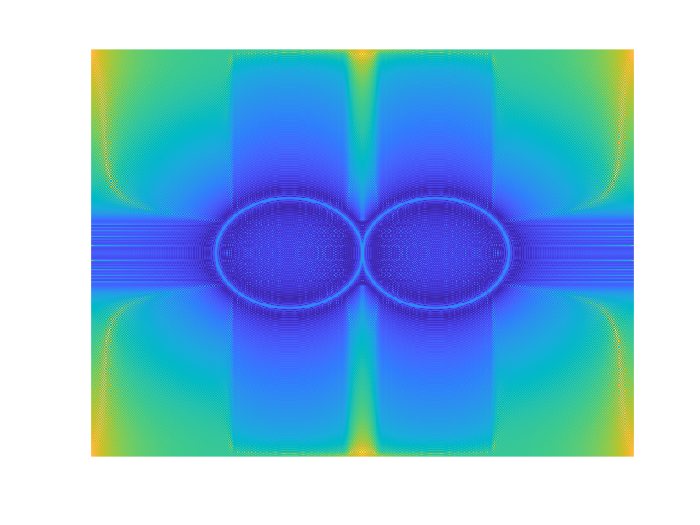

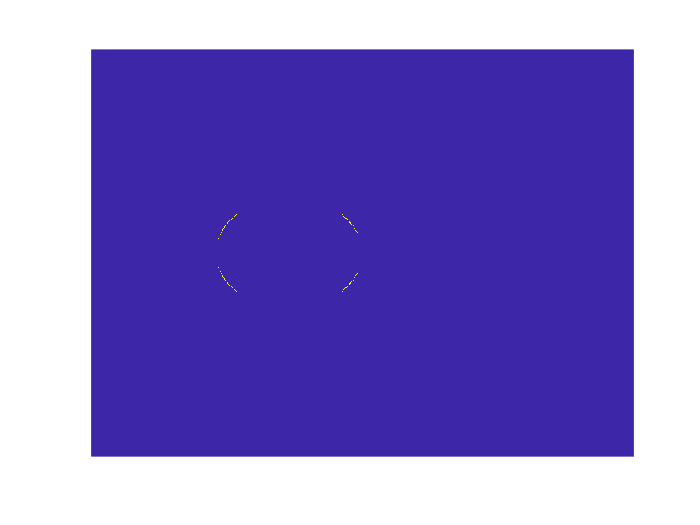

clear
lambda = 670e-9;
f_sca = SctCoef(lambda);
row = 481;
col = 641;

alpha = 0.01;
gamma = 10e-6;

deltaDistance = 74e-9;
x = linspace(1,col,col);
y = linspace(1,row,row);
[X,Y] = meshgrid(x,y);
R = hypot(X-ceil(col/2),Y-ceil(row/2))*deltaDistance;
Ei = exp(1i*f_sca.kspp*X*deltaDistance);
Es = alpha*exp(-R/f_sca.PropagationLength) ...
    .*exp(1i*f_sca.kspp*R) ...
    *exp(1i*angle(Ei(ceil(row/2),ceil(col/2))));
I = abs(Es+Ei).^2 - abs(Ei).^2 - abs(Es).^2;

F = fftshift(fft2(ifftshift(I)));
[center_raw,center_col,R,~] = findcircle(log(abs(F)),5,0,1);

peaks = [center_col,center_raw,R];

mask = EwaldMask(F,peaks,0.15,'G',2,'in');
I_rcn = abs(fftshift(ifft2(ifftshift(F.*mask))));
h = ones(3,3);
I_rcn = conv2(I_rcn,h,'same');
close all

std_SPR = I(ceil(row/2),ceil(col/2))

std_SPR = 0.0200

std_Rcn = I_rcn(ceil(row/2),ceil(col/2))

std_Rcn = 0.0762

# **开始循环计算**

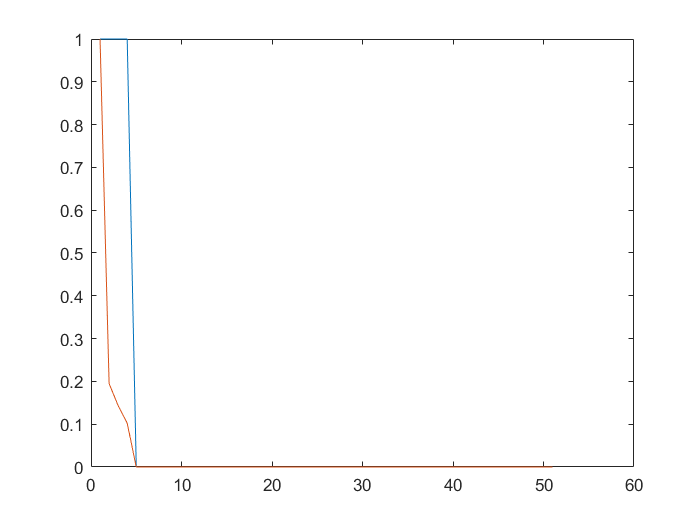

N = 100;
M = 201;
kk = 0;
Valid_Num_0f_Rcn = zeros(51,1);
Valid_Num_of_Spr = Valid_Num_0f_Rcn;
for ii = linspace(1,4,M)
    kk = kk + 1;
    N_Rcn = 0;
    N_Spr = 0;
    for jj = 1:N
        [I,Es,pst] = rand_spr(ii, ...
            f_sca.wavelength, ...
            sqrt(f_sca.epsilon_water), ...
            f_sca.ResonanceAngle, ...
            alpha, ...
            f_sca.PropagationLength);
        F = fftshift(fft2(ifftshift(I)));
        pst = sub2ind([row,col],pst(:,1),pst(:,2));
        I_rcn = abs(fftshift(ifft2(ifftshift(F.*mask))));
        h = ones(3,3);
        I_rcn = conv2(I_rcn,h,'same');
        int_rcn = I_rcn(pst);
        int_spr = I(pst);
        int_rcn = abs(int_rcn-std_Rcn)/std_Rcn;
        int_spr = abs(int_spr-std_SPR)/std_SPR;
        N_Rcn = N_Rcn + sum(int_rcn <= 0.05);
        N_Spr = N_Spr + sum(int_spr <= 0.05);
    end
    
    Valid_Num_0f_Rcn(kk) = N_Rcn/N/ii;
    Valid_Num_of_Spr(kk) = N_Spr/N/ii;
end

figure
plot(Valid_Num_0f_Rcn);
hold on
plot(Valid_Num_of_Spr);

# **作图**

clear

load('D:\工作汇总\文章\散射场重构\文章图片\SI\图片\S5\1_201_51_Rcn_Spr_cmp_边缘20个像素不用.mat');

figure
plot(Valid_Num_0f_Rcn);
hold on
plot(Valid_Num_of_Spr);
xlim([0 51])
ylim([0 1.1])
legend({'Reconstruction','SPRM'})
xlabel('Number of Particles in The Field of View')
ylabel('Accuracy Rate (%)')

hf = findobj(gca,'type','line');
hf(2).YData = Valid_Num_of_Spr;
hf(3).YData = Valid_Num_0f_Rcn;

x = 1:200;
y1 = interp1((1:51)*4-3,Valid_Num_of_Spr,x);
y2 = interp1((1:51)*4-3,Valid_Num_0f_Rcn,x);
y1(1:4) = Valid_Num_of_Spr(1:4);
y2(1:4) = Valid_Num_0f_Rcn(1:4);

figure
plot(y1)
hold on
plot(y2)
hf(2).YData = y1;
hf(3).YData = y2;
xlim([0 201])
line([1 201],[0.8 0.8],'color','black')